clc;
clear;

% === Drone Simulation Parameters ===
dt = 0.01; % Time step (seconds)
simulation_time = 100; % Total simulation time (seconds)
time = 0:dt:simulation_time;

% === PID Gains ===
Kp_xy = 0.111;
Kd_xy = 0.1804;
Kp_z = 0.8173;
Kd_z = 2.214;

% === Environment Parameters ===
g = 9.81; % Gravity (m/s^2)

% === Initial Conditions ===
goal_position = [0, 0, 1]; % Desired goal position
vicon_position = [0.4, 0.4, 0]; % [x, y, z]
vicon_velocity = [0, 0, 0]; % [vx, vy, vz]
yaw = 0; % Assume zero yaw for now

% === Storage for analysis ===
errors_global = zeros(length(time), 3);
errors_local = zeros(length(time), 2);
thrust_values = zeros(length(time), 1);
roll_pitch_values = zeros(length(time), 2);
position_log = zeros(length(time), 3);

fprintf("=== Drone Simulation Started ===\n");

=== Drone Simulation Started ===


fprintf("  Time |        X        Y        Z |     ErrX     ErrY     ErrZ |    Roll   Pitch  Thrust\n");

  Time |        X        Y        Z |     ErrX     ErrY     ErrZ |    Roll   Pitch  Thrust



for t = 1:length(time)
    % --- Error calculation ---
    error_global = goal_position - vicon_position;
    errors_global(t, :) = error_global;

    % --- Transform to local frame (assuming yaw = 0 for now) ---
    x_err_local = cos(yaw) * error_global(1) + sin(yaw) * error_global(2);
    y_err_local = -sin(yaw) * error_global(1) + cos(yaw) * error_global(2);
    errors_local(t, :) = [x_err_local, y_err_local];

    % --- Derivatives ---
    if t == 1
        dx = 0;
        dy = 0;
        dz = 0;
    else
        dx = (errors_local(t, 1) - errors_local(t-1, 1)) / dt;
        dy = (errors_local(t, 2) - errors_local(t-1, 2)) / dt;
        dz = (errors_global(t, 3) - errors_global(t-1, 3)) / dt;
    end

    % --- PD Control: Roll and Pitch (convert to radians) ---
    roll_cmd  = Kp_xy * y_err_local + Kd_xy * dy;
    pitch_cmd = -(Kp_xy * x_err_local + Kd_xy * dx);
    roll_cmd  = max(min(deg2rad(roll_cmd), 0.2), -0.2);
    pitch_cmd = max(min(deg2rad(pitch_cmd), 0.2), -0.2);
    roll_pitch_values(t, :) = [roll_cmd, pitch_cmd];

    % --- PD Control: Thrust (vertical control) ---
    thrust_cmd = Kp_z * error_global(3) + Kd_z * dz + g;
    thrust_cmd = max(min(thrust_cmd, 15), 0); % Limit max thrust to prevent launch into space
    thrust_values(t) = thrust_cmd;

    % --- Acceleration Calculation (Fixed Model) ---
    accel_x = -thrust_cmd * sin(pitch_cmd);
    accel_y = thrust_cmd * sin(roll_cmd);
    accel_z = thrust_cmd * cos(roll_cmd) * cos(pitch_cmd) - g;
    acceleration = [accel_x, accel_y, accel_z];

    % --- Update Velocity and Position ---
    vicon_velocity = vicon_velocity + acceleration * dt;
    vicon_position = vicon_position + vicon_velocity * dt;
    position_log(t, :) = vicon_position;

    % --- Print Status ---
    if mod(t, round(1/dt)) == 1 || t == length(time)
        fprintf("%6.2f | %8.3f %8.3f %8.3f | %9.3f %9.3f %9.3f | %7.3f %7.3f %6.3f\n", ...
            time(t), ...
            vicon_position(1), vicon_position(2), vicon_position(3), ...
            error_global(1), error_global(2), error_global(3), ...
            roll_cmd, pitch_cmd, thrust_cmd);
    end

    % --- Safety Check ---
    if norm(vicon_position) > 100
        warning("Drone flew too far. Simulation aborted for safety.");
        break;
    end
end

  0.00 |    0.400    0.400    0.000 |    -0.400    -0.400     1.000 |  -0.001   0.001 10.627
  1.00 |    0.396    0.396    0.214 |    -0.396    -0.396     0.789 |  -0.001   0.001  9.814
  2.00 |    0.385    0.385    0.480 |    -0.385    -0.385     0.523 |  -0.001   0.001  9.726
  3.00 |    0.366    0.366    0.669 |    -0.367    -0.367     0.333 |  -0.001   0.001  9.743
  4.00 |    0.342    0.342    0.792 |    -0.342    -0.342     0.209 |  -0.001   0.001  9.765
  5.00 |    0.312    0.312    0.869 |    -0.312    -0.312     0.132 |  -0.001   0.001  9.782
  6.00 |    0.277    0.277    0.918 |    -0.278    -0.278     0.083 |  -0.000   0.000  9.792
  7.00 |    0.238    0.238    0.948 |    -0.239    -0.239     0.052 |  -0.000   0.000  9.799
  8.00 |    0.196    0.196    0.968 |    -0.196    -0.196     0.032 |  -0.000   0.000  9.803
  9.00 |    0.151    0.151    0.980 |    -0.152    -0.152     0.020 |  -0.000   0.000  9.806
 10.00 |    0.105    0.105    0.987 |    -0.106    -0.106     0.013 | 


fprintf("=== Simulation Complete ===\n");

=== Simulation Complete ===


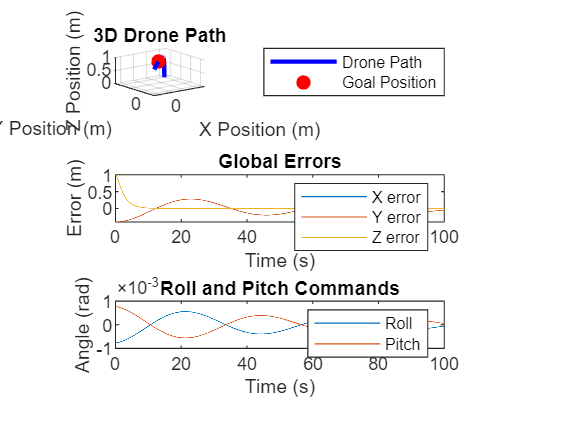


% === Plotting ===
figure;

% 3D plot of the drone's movement
subplot(3, 1, 1);
plot3(position_log(:,1), position_log(:,2), position_log(:,3), 'b-', 'LineWidth', 2);
hold on;
plot3(goal_position(1), goal_position(2), goal_position(3), 'ro', 'MarkerFaceColor', 'r');
title('3D Drone Path');
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
legend('Drone Path', 'Goal Position');
grid on;

% Plot Global Errors
subplot(3, 1, 2);
plot(time, errors_global);
title('Global Errors');
xlabel('Time (s)');
ylabel('Error (m)');
legend('X error', 'Y error', 'Z error');

% Plot Roll, Pitch, and Thrust Commands
subplot(3, 1, 3);
plot(time, roll_pitch_values);
title('Roll and Pitch Commands');
xlabel('Time (s)');
ylabel('Angle (rad)');
legend('Roll', 'Pitch');